We consider a clamped-pinned beam. 

Nayfeh [1] and Li [2] inverstigated the forced response of such a system under external harmonic response. Specifically, modal expansion (with linear modes) is used to transfer PDEs to a set of ODEs


$$\ddot{u}_n+\omega_n^2u_n=-2c_n\dot{u}_n+\nu\sum_{m,p,q}\alpha_{nmpq}u_mu_pu_q+\epsilon\left(f_n\cos\lambda t\right), n=1,\cdots,$$


This set of ODEs has to be adjusted for the case where the harmonic excitation  $p_a(t)$ occurs in an axial direction and direct transverse excitation is applied as $p_t(x,t)$, where $x$ are dimensionless coordinates along the beam . Then the equations of the modal coordinates in transverse direction read

 
$$\omega_j^2 u_j + \ddot{u}_j +  2c_j\dot{u}_j= \nu\sum_{i,k,s} \alpha_{jiks} u_i u_k u_s   + \epsilon \bigg(f_j(t) + \sum_i p_a(t) u_i a_{ji}\bigg)$$


where the coefficients $a_{ji}$ are defined in terms of the spatial eigenmodes as


$$a_{ji} := \int_0^l  \psi_j \ \psi''_i dx$$


and


$$f_j = \int_0^l  \psi_j p(x,t) dx$$


Here no mode is ecited externall so $f_j = 0$ for all $j$ and $p_a(t) = \mu \cos(\Omega t)$. The system is forced around the principal resonance of the first mode so $\Omega \approx 2\omega_1$

[1] Nayfeh, A. H., Mook, D. T., & Sridhar, S. (1974). Nonlinear analysis of the forced response of structural elements. *The Journal of the Acoustical Society of America*, *55*(2), 281-291.

[2] M. Li, S. Jain, and G. Haller.  Nonlinear analysis of forced mechanical systems with internal resonance using spectralsubmanifolds–part I: Periodic response and forced response curve.* arXiv preprint *arXiv:2106.05162, 2021

## Setup Dynamical System

clear all;
rLsq = 1e-4;
n =10;
c = 200;

[mass,damp,stiff,fnl,fext] = build_model_parametric(c,rLsq,n);

Getting nonlinearity coefficients
Loaded coefficients from storage
Loaded coefficients from storage



% Create 
DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% Forcing
DS.add_forcing(fext);

## Linear Modal Analysis 

% Analyse spectrum
[V,D,W_evec] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.748056e-03
modal damping ratio for 2 mode is 1.156678e-03
modal damping ratio for 3 mode is 5.544682e-04
modal damping ratio for 4 mode is 3.242164e-04
modal damping ratio for 5 mode is 2.124757e-04

 The first 10 eigenvalues are given as 
  -0.0200 + 5.3361i
  -0.0200 - 5.3361i
  -0.0200 +17.2909i
  -0.0200 -17.2909i
  -0.0200 +36.0706i
  -0.0200 -36.0706i
  -0.0200 +61.6872i
  -0.0200 -61.6872i
  -0.0200 +94.1284i
  -0.0200 -94.1284i



#### Choose Master subspace (perform resonance analysis)

% Set up SSM object
S = SSM(DS);
set(S.Options, 'reltol', 0.3,'notation','multiindex')

%Choose Master subspace
resModes = [1,2];
S.choose_E(resModes);

sigma_out = 1
sigma_in = 1


## Forced response curves using SSMs

% Obtaining *forced response curve* in reduced-polar coordinate

order = 7; % Approximation order
%% 
% setup options

outdof = 1;
set(S.Options,    'reltol', 0.5,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7)
set(S.FRCOptions, 'outdof',outdof, 'coordinates','cartesian')
set(S.FRCOptions, 'branchSwitch',true,'periodsRatio',2) %continue BPs of primary branch, 2T response
set(S.contOptions,'PtMX',100,'h_min',1e-4,'h0',1e-4,'bi_direct',false)
set(S.contOptions, 'NAdapt',1,'h_max',50)
%% 
% choose frequency range around the master mode frequency

omega0 = imag(S.E.spectrum(1));
OmegaRange =[10.62,13]   % Subharmonic resonance at Omega = 2 omega_0

epSamp = [0.11, 0.115, 0.12, 0.125, 0.13 ];

OmegaRange =    10.4880   11.2057


### Extract forced response curve

sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 5.72E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 6.26E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 7.27E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 8.53E-02 MB

 Run='SSMsweep0.1.po': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.52e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om    po.period         amp1        Znorm
    0  00:00:01   1.5185e+01      1  EP      1.0672e+01   1.1775e+00   0.0000e+00   0.0000e+00
   10  00:00:07   1.5251e+01      2          1.0720e+01   1.1722e+00   0.0000e+00   0.0000e+00
   14  00:00:09   1.

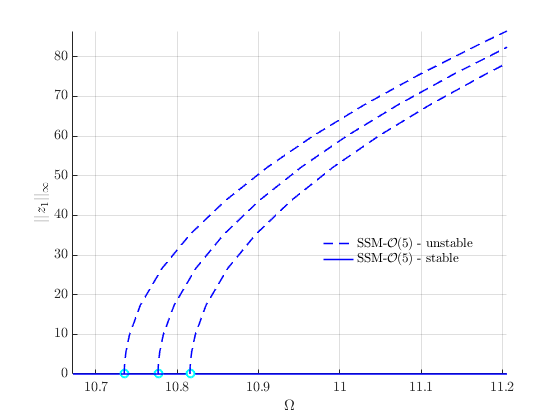


figure()
startFRCSSM = tic;
Sweep = S.SSM_poSweeps('SSMsweep',resModes,order,epSamp,OmegaRange);

timings.FRCSSM = toc(startFRCSSM)

timings = struct with fields:
    FRCSSM: 132.6297


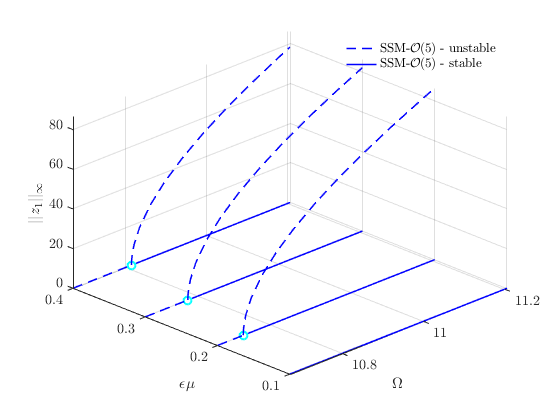



% Forcing amplitude is mu*epsilon
ylabel('$\epsilon \mu$','Interpreter','latex'); 


figFRC = gcf;

## Verification: Collocation using [coco](https://sourceforge.net/p/cocotools/wiki/Home/)

Dankowicz, H., & Schilder, F. (2013).  *Recipes for Continuation,* SIAM Philadelphia. [<https://doi.org/10.1137/1.9781611972573](https://doi.org/10.1137/1.9781611972573)>

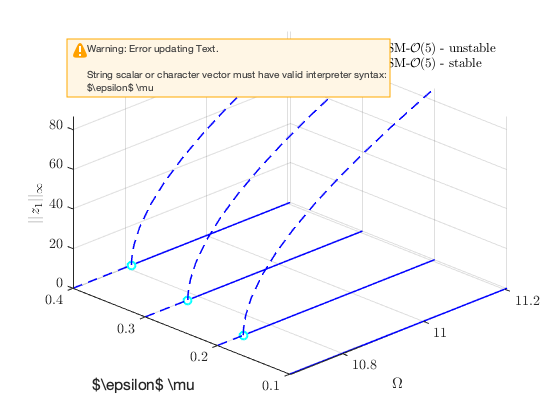

%% Get results from full system
nCycles = 10;

coco = cocoWrapper(DS, nCycles, outdof);
set(coco,'initialGuess','forward')
set(coco,'branchSwitch',false,'periodsRatio',2) % include new branches, 2T periodic response
set(coco.Options, 'NAdapt', 1);
set(coco.Options,'ItMX',15,'NTST', 70,'PtMX',500,'bi_direct',false,'h0',1e-4,'h_max',50); %for convergence, smaller stepsize

figure(figFRC)
hold on

startcoco = tic;
Sweep_coco = coco.coco_poSweeps(epSamp,OmegaRange);


 Run='FRC0.1': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.49e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1
    0  00:00:04   1.4929e+01      1  EP      1.0488e+01   1.1982e+00   1.0000e-01   0.0000e+00


timings.cocoFRC = toc(startcoco)

## Stability Diagram: Initial condition and parameter range


omega0 = imag(S.E.spectrum(1));
p0 = [2*omega0,0.01]; % Initial condition
 
OmegaRange =[10.3,11];
epRange = [0,1];
PlotSD = false;

clear S
% Set up SSM object
S = SSM(DS);
set(S.Options, 'reltol', 0.3,'notation','multiindex')

%Choose Master subspace
resModes = [1,2];
S.choose_E(resModes);

% Options
set(S.contOptions,'PtMX',40,'bi_direct',true)
set(S.FRCOptions,'branchSwitch',true)

SD = S.extract_Stability_Diagram(resModes, order, OmegaRange,epRange,'amp', p0,'PD',PlotSD);



Plots for Paper

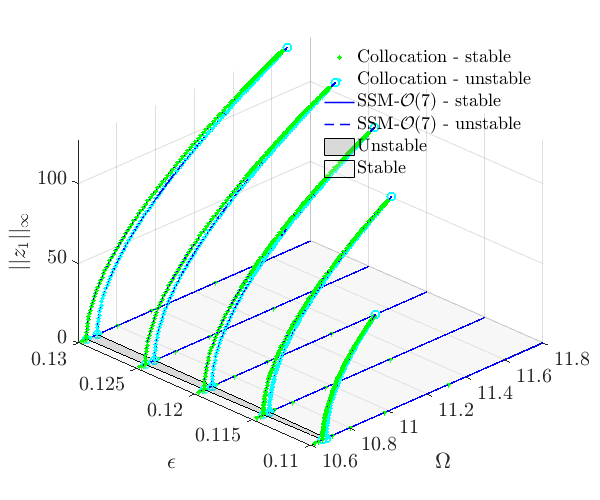

PBplotSweep(Sweep.FRCom,Sweep_coco,outdof,order)
PBplotSDinSweep(gcf,SD,11.9)
xlim([10.6,11.8])
ylim([0.11,0.13])